# FACET-II Accelerator Science Example # 1: BPM Orbit Fitting, Correction and Bump Generation

This example involves taking BPM data (either live or from the archiver, and additionally live buffered data) and performing orbit fitting using the Live Lucretia Model.

**NB: This example neeeds access to EPICS IOC's through the FACET controls system and assumes matlab v.2020a+, started in the matlabTNG/ directory.**

**This example requires a live beam present through to the dump for the tasks to operate as intended and completely make sense.**

clear

## Task 1: Load live Lucretia model, instantiate BPM & Corrector objects and checkout acquisition functionality

The following command loads the Lucretia model from the default design location and synchronizes Klystrons, Quads, Sextupoles with control system values and sets energy profile.

LLM = F2_LiveModelApp ;

10-Apr-2022 21:48:14:
Starting LEM Application...
10-Apr-2022 21:48:14:
Loading Lucretia Model...
10-Apr-2022 21:48:19:
Linking to EPICS PVs...
Initial Eref:
    0.0060    0.1251    0.3394    4.5000    9.3000

10-Apr-2022 21:48:19:
Updating with live data...
    0.0060    0.1250    0.2735    4.3048    9.2654

    0.0060    0.1251    0.3398    4.5671    9.5625

    0.0060    0.1251    0.3394    4.4993    9.2307

    0.0060    0.1251    0.3394    4.5000    9.3011

    0.0060    0.1251    0.3394    4.5000    9.3000

10-Apr-2022 21:48:32:
Initialization complete.


The returned `LiveModel` object `LLM `is mostly a container for the underlying model objects we care about: principally the `LucretiaModel` object found in `LLM.LM` and the `LEM` object (which contains most of the smarts for syncing the model with the controls) found in `LLM.LEM`. An important method is `UpdateModel` which can be called to refresh the model with external changes in the control system (a future update will provide for the possibility of autoupdating).

We make our own local copy of a `LucretiaModel` object for playing with- the copy command is important as simply re-assigning it (e.g. as `LM=LLM.LM`) will just make a pointer to the original.

LM = copy(LLM.LM) ; % Make our own local copy of the LucretiaModel

By default,  objects will operate on the entire machine. Sometimes it can be helpful to work on a reduced set of objects, for example to speed up data retieval. The machine is subdivided into 11 regions, the definition for which can be found in the `LucretiaModel` class.

disp(LucretiaModel.ModelRegionName)

    "INJ"
    "L0"
    "DL1"
    "L1"
    "BC11"
    "L2"
    "BC14"
    "L3"
    "BC20"
    "FFS"
    "SPECTDUMP"



Here, lets concentrate just on the L3 linac section, plus BC20. Then make BPM and Magnet objects.

LM.UseRegion = [0 0 0 0 0 0 0 1 1 0 0] ; % Select L3+BC20 only
BPMS = F2_bpms(LM) ; % F2_bpms makes its own copy of the LucretiaModel

Setting severity REJECTION level to 4


MAGS = F2_mags(LM) ; % F2_mags makes its own copy of the LucretiaModel

Now, we shall refine the MAGS class to make a Corrector object.

COR = copy(MAGS) ; COR.MagClasses = ["XCOR" "YCOR"] ;

Lets now fetch the current BDES values from the control system for the correctors.

COR.ReadB ;

**NB: the **`readB`** method stores the control system values only locally to the F2_mags object, the in-memory Lucretia model is defined by the global variables (BEAMLINE,PS,KLYSTRON). To both read in the new values AND set them into the in-memory model, use **`readB(true)`**.**

Take a look at the read values by putting it into a Matlab table.

COR_Name = COR.LM.ModelNames ; % Using a LucretiaModel object method attached to the F2_mags object to grab names
COR_BDES = COR.BDES_cntrl; COR_BACT = COR.BACT_cntrl; COR_BMAX = COR.BMAX;
disp(table(COR_Name,COR_BDES,COR_BACT,COR_BMAX)) ;

    COR_Name      COR_BDES       COR_BACT      COR_BMAX
    _________    ___________    ___________    ________

    "XC14900"      -0.018256      -0.018252    0.06243 
    "YC14900"      0.0039191      0.0039195    0.06243 
    "XC15202"       0.017524       0.017524    0.06243 
    "YC15203"              0     4.4993e-05    0.06243 
    "XC15302"              0      1.596e-05    0.06243 
    "YC15303"       0.019667       0.019662    0.06243 
    "XC15402"       0.010802         0.0108    0.06243 
    "YC15403"              0    -1.5099e-06    0.06243 
    "XC15502"              0     1.7774e-05    0.06243 
    "YC15503"      0.0040953      0.0040859    0.06243 
    "XC15602"      0.0060823      0.0060821    0.06243 
    "YC15603"              0    -5.2682e-06    0.06243 
    "XC15702"              0     1.2177e-05    0.06243 
    "YC15703"     -0.00

Now lets turn to the BPMS. First, try getting 10 BPM readings from the EPICS BPM repeater and plotting the orbit.

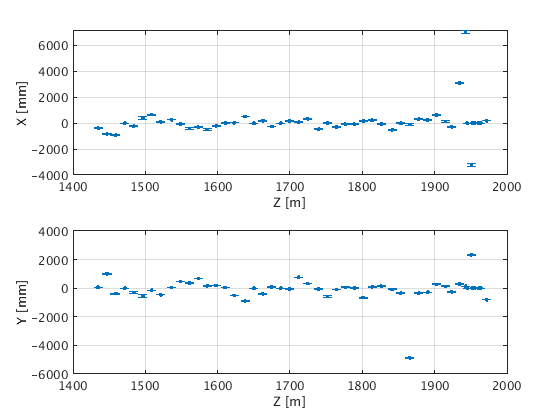

BPMS.readnp(10) ;
BPMS.plot ;

NB: the raw data is stored in BPMS.xdat / ydat / tmit . Lets look at some derived data in a table.

BPM_Name = BPMS.modelnames ; % There is also "bpmnames" which has the the control system BPM names
Z = BPMS.modelZ ; % Linac z co-ordinate
X_mean = BPMS.xave ; Y_mean = BPMS.yave ;
X_err = BPMS.xrms ; Y_err = BPMS.yrms ;
TMIT_mean = BPMS.tmitave; TMIT_err = BPMS.tmitrms ;
disp(table(BPM_Name,Z,X_mean,X_err,Y_mean,Y_err,TMIT_mean,TMIT_err)) ;

     BPM_Name       Z         X_mean        X_err       Y_mean        Y_err      TMIT_mean      TMIT_err 
    __________    ______    __________    _________    _________    _________    __________    __________

    "BPM15201"    1434.7      -0.38576      0.01766     0.062184     0.017542    4.7046e+09    6.8639e+07
    "BPM15301"      1447      -0.83247     0.023935       1.0035     0.023325    4.4104e+09    9.0283e+07
    "BPM15401"    1459.4      -0.92152      0.04472     -0.38001     0.040204    4.6597e+09    8.5701e+07
    "BPM15501"    1471.7             0            0            0            0             0             0
    "BPM15601"      1484      -0.23479     0.033313     -0.29212     0.065683    4.6888e+09

`readbp` simply reads from the EPICS PVs at the beam rate, it isn't guaranteed that the individual readings are synchronous. To achieve this, we use the `readbuffer` method which reads BPM data from BSA EPICS and/or uses AIDA-PVA SCP BUFFACQ as required (and additionally matches up the pulse ID's as needed).

BPMS.readbuffer(20) ; % The stored data is synchronous
fprintf(BPMS.nread+" Pulses acquired\n") ;

20 Pulses acquired


NB: there is an uncertain delay in launching the command to acquire data through AIDA-PVA. To ensure that the EPICS and SCP data overlap, additional EPICS data is taken. This additional fraction is set by the `nepicsbuffer` property and can be increased if fully overlapping data is not acquired (as reported in the `nread` property).

Finally, lets grab 10 BPM readings from the archiver (these are never going to be pulse-synchronous and should only be used for averaging).

BPMS.readnp(10,[2022 4 10 21 22 0]);

Reading BPMS:LI15:201:X57
Calling singleHistory
Asking history for BPMS:LI15:201:X57 from 2022-04-11T04:22:00.000Z to 2022-04-11T04:23:40.000Z
mshankar Done getting history for BPMS:LI15:201:X57 from 2022-04-11T04:22:00.000Z to 2022-04-11T04:23:40.000Z
Reading BPMS:LI15:301:X57
Calling singleHistory
Asking history for BPMS:LI15:301:X57 from 2022-04-11T04:22:00.000Z to 2022-04-11T04:23:40.000Z
mshankar Done getting history for BPMS:LI15:301:X57 from 2022-04-11T04:22:00.000Z to 2022-04-11T04:23:40.000Z
Reading BPMS:LI15:401:X57
Calling singleHistory
Asking history for BPMS:LI15:401:X57 from 2022-04-11T04:22:00.000Z to 2022-04-11T04:23:40.000Z
mshankar Done getting history for BPMS:LI15:401:X57 from 2022-04-11T04:22:00.000Z to 2022-04-11T04:23:40.000Z
Reading BPMS:LI15:501:X57
Calling singleHistory
Asking history for BPMS:LI15:501:X57 from 2022-04-11T04:22:00.000Z to 2022-04-11T04:23:40.000Z
mshankar Done getting history for BPMS:LI15:501:X57 from 2022-04-11T04:22:00.000Z to 2022-04-11T04

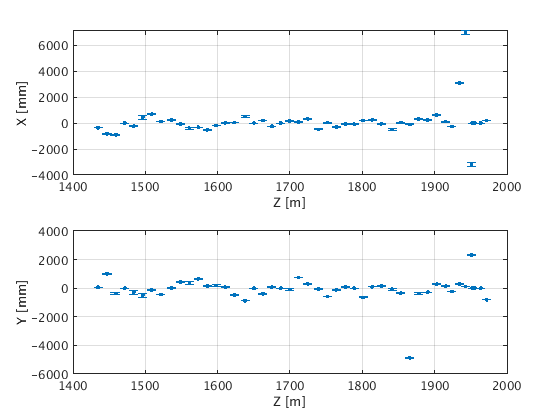

BPMS.plot ;